Primeramente para encontrar donde se encuentra el ventriculo izquiero utilice bwlebel que basicamente me dice clasfica objetos que estan juntos en la matriz. 

El valor que se le impuso a cada uno fue revisado graficando la imagen y buscandolo en la matriz; y este depende de la segmentacion de la imagen

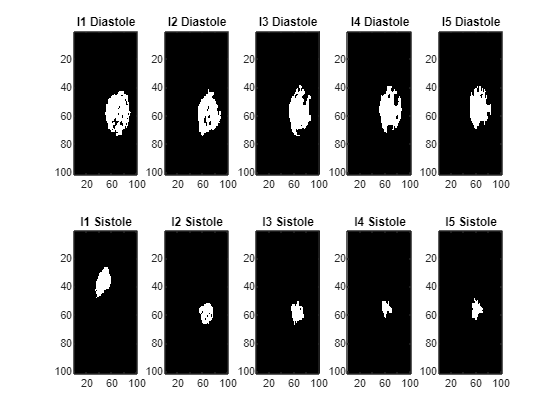

% Morfologia Matematica

M1_BW1_D  = bwlabel(im1_D_bin) == 13;
M1_BW2_D  = bwlabel(im2_D_bin)==14;
M1_BW3_D  = bwlabel(im3_D_bin)==14;
M1_BW4_D  = bwlabel(im4_D_bin)==13;
M1_BW5_D  = bwlabel(im5_D_bin)==15;

M1_BW1_S = bwlabel(im1_S_bin) == 18;
M1_BW2_S = bwlabel(im2_S_bin)==18;
M1_BW3_S = bwlabel(im3_S_bin)==18;
M1_BW4_S = bwlabel(im4_S_bin)==18;
M1_BW5_S = bwlabel(im5_S_bin)==13;


% Mostrando imagenes con zona de interes
figure;
subplot(2,5,1);
imagesc(M1_BW1_D); colormap('gray'); title('I1 Diastole');
subplot(2,5,6);
imagesc(M1_BW1_S); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);
imagesc(M1_BW2_D); colormap('gray'); title('I2 Diastole');
subplot(2,5,7);
imagesc(M1_BW2_S); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);
imagesc(M1_BW3_D); colormap('gray'); title('I3 Diastole');
subplot(2,5,8);
imagesc(M1_BW3_S); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);
imagesc(M1_BW4_D); colormap('gray'); title('I4 Diastole');
subplot(2,5,9);
imagesc(M1_BW4_S); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);
imagesc(M1_BW5_D); colormap('gray'); title('I5 Diastole');
subplot(2,5,10);
imagesc(M1_BW5_S); colormap('gray'); title('I5 Sistole');

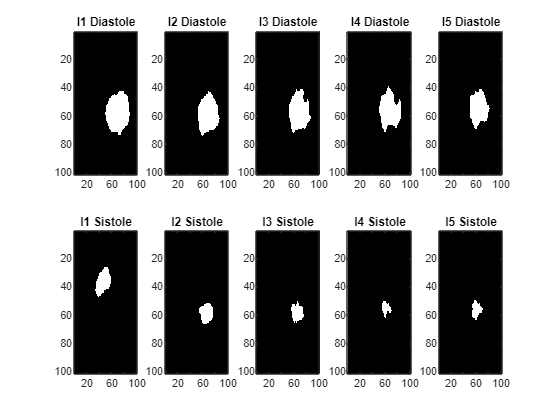

% Elementos estructurantes
SE1 = strel('disk', 1);
SE2 = strel('disk', 2);
SE4 = strel('disk', 4);

% ---- DIÁSTOLE ----
% 1) Rellenar huecos cerrados
M1_BW1_D_f = imfill(M1_BW1_D, 'holes');
M1_BW2_D_f = imfill(M1_BW2_D, 'holes');
M1_BW3_D_f = imfill(M1_BW3_D, 'holes');
M1_BW4_D_f = imfill(M1_BW4_D, 'holes');
M1_BW5_D_f = imfill(M1_BW5_D, 'holes');

% 2) Apertura: saca espículas y bordes dentados
M1_BW1_D_op = imopen(M1_BW1_D_f, SE2);
M1_BW2_D_op = imopen(M1_BW2_D_f, SE2);
M1_BW3_D_op = imopen(M1_BW3_D_f, SE2);
M1_BW4_D_op = imopen(M1_BW4_D_f, SE2);
M1_BW5_D_op = imopen(M1_BW5_D_f, SE2);

% 3) Cierre: tapa muescas abiertas en el borde
M1_BW1_D_cl = imclose(M1_BW1_D_op, SE4);
M1_BW2_D_cl = imclose(M1_BW2_D_op, SE4);
M1_BW3_D_cl = imclose(M1_BW3_D_op, SE4);
M1_BW4_D_cl = imclose(M1_BW4_D_op, SE4);
M1_BW5_D_cl = imclose(M1_BW5_D_op, SE4);

% 4) Rellenar de nuevo (el cierre puede crear huecos)
M1_BW1_D_fin = imfill(M1_BW1_D_cl, 'holes');
M1_BW2_D_fin = imfill(M1_BW2_D_cl, 'holes');
M1_BW3_D_fin = imfill(M1_BW3_D_cl, 'holes');
M1_BW4_D_fin = imfill(M1_BW4_D_cl, 'holes');
M1_BW5_D_fin = imfill(M1_BW5_D_cl, 'holes');

% ---- SÍSTOLE (radios más chicos porque la cavidad es más chica) ----
M1_BW1_S_f = imfill(M1_BW1_S, 'holes');
M1_BW2_S_f = imfill(M1_BW2_S, 'holes');
M1_BW3_S_f = imfill(M1_BW3_S, 'holes');
M1_BW4_S_f = imfill(M1_BW4_S, 'holes');
M1_BW5_S_f = imfill(M1_BW5_S, 'holes');

M1_BW1_S_op = imopen(M1_BW1_S_f, SE1);
M1_BW2_S_op = imopen(M1_BW2_S_f, SE1);
M1_BW3_S_op = imopen(M1_BW3_S_f, SE1);
M1_BW4_S_op = imopen(M1_BW4_S_f, SE1);
M1_BW5_S_op = imopen(M1_BW5_S_f, SE1);

M1_BW1_S_cl = imclose(M1_BW1_S_op, SE2);
M1_BW2_S_cl = imclose(M1_BW2_S_op, SE2);
M1_BW3_S_cl = imclose(M1_BW3_S_op, SE2);
M1_BW4_S_cl = imclose(M1_BW4_S_op, SE2);
M1_BW5_S_cl = imclose(M1_BW5_S_op, SE2);

M1_BW1_S_fin = imfill(M1_BW1_S_cl, 'holes');
M1_BW2_S_fin = imfill(M1_BW2_S_cl, 'holes');
M1_BW3_S_fin = imfill(M1_BW3_S_cl, 'holes');
M1_BW4_S_fin = imfill(M1_BW4_S_cl, 'holes');
M1_BW5_S_fin = imfill(M1_BW5_S_cl, 'holes');

% Mostrando resultado final
figure;
subplot(2,5,1);  
imagesc(M1_BW1_D_fin); colormap('gray'); title('I1 Diastole');

subplot(2,5,6);  
imagesc(M1_BW1_S_fin); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);  
imagesc(M1_BW2_D_fin); colormap('gray'); title('I2 Diastole');

subplot(2,5,7);  
imagesc(M1_BW2_S_fin); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);  
imagesc(M1_BW3_D_fin); colormap('gray'); title('I3 Diastole');

subplot(2,5,8);  
imagesc(M1_BW3_S_fin); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);  
imagesc(M1_BW4_D_fin); colormap('gray'); title('I4 Diastole');

subplot(2,5,9);  
imagesc(M1_BW4_S_fin); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);  
imagesc(M1_BW5_D_fin); colormap('gray'); title('I5 Diastole');

subplot(2,5,10); 
imagesc(M1_BW5_S_fin); colormap('gray'); title('I5 Sistole');

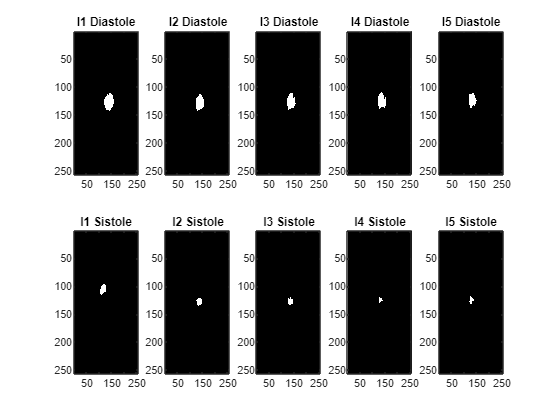

%% ================== Reshape image ===========================

originalSize = size(im1_D);   % tamaño real de los DICOM (lo leo de la imagen en vez de asumir 256x256)

M1_img1_D_res = PadToOriginal(M1_BW1_D_fin, idx1, idx2, originalSize);
M1_img2_D_res = PadToOriginal(M1_BW2_D_fin, idx1, idx2, originalSize);
M1_img3_D_res = PadToOriginal(M1_BW3_D_fin, idx1, idx2, originalSize);
M1_img4_D_res = PadToOriginal(M1_BW4_D_fin, idx1, idx2, originalSize);
M1_img5_D_res = PadToOriginal(M1_BW5_D_fin, idx1, idx2, originalSize);

M1_img1_S_res = PadToOriginal(M1_BW1_S_fin, idx1, idx2, originalSize);
M1_img2_S_res = PadToOriginal(M1_BW2_S_fin, idx1, idx2, originalSize);
M1_img3_S_res = PadToOriginal(M1_BW3_S_fin, idx1, idx2, originalSize);
M1_img4_S_res = PadToOriginal(M1_BW4_S_fin, idx1, idx2, originalSize);
M1_img5_S_res = PadToOriginal(M1_BW5_S_fin, idx1, idx2, originalSize);

% Mostramos los resultados en tamaño original
figure;
subplot(2,5,1);  imagesc(M1_img1_D_res); colormap('gray'); title('I1 Diastole');
subplot(2,5,2);  imagesc(M1_img2_D_res); colormap('gray'); title('I2 Diastole');
subplot(2,5,3);  imagesc(M1_img3_D_res); colormap('gray'); title('I3 Diastole');
subplot(2,5,4);  imagesc(M1_img4_D_res); colormap('gray'); title('I4 Diastole');
subplot(2,5,5);  imagesc(M1_img5_D_res); colormap('gray'); title('I5 Diastole');

subplot(2,5,6);  imagesc(M1_img1_S_res); colormap('gray'); title('I1 Sistole');
subplot(2,5,7);  imagesc(M1_img2_S_res); colormap('gray'); title('I2 Sistole');
subplot(2,5,8);  imagesc(M1_img3_S_res); colormap('gray'); title('I3 Sistole');
subplot(2,5,9);  imagesc(M1_img4_S_res); colormap('gray'); title('I4 Sistole');
subplot(2,5,10); imagesc(M1_img5_S_res); colormap('gray'); title('I5 Sistole');


fprintf('-----Resultados con morfología matemática----- \n');

-----Resultados con morfología matemática----- 


fprintf('FE estimada IMG 1: %g\n', (sum(M1_img1_D_res(:)) - sum(M1_img1_S_res(:)))/sum(M1_img1_D_res(:)));

FE estimada IMG 1: 0.621229


fprintf('FE estimada IMG 2: %g\n', (sum(M1_img2_D_res(:)) - sum(M1_img2_S_res(:)))/sum(M1_img2_D_res(:)));

FE estimada IMG 2: 0.668901


fprintf('FE estimada IMG 3: %g\n', (sum(M1_img3_D_res(:)) - sum(M1_img3_S_res(:)))/sum(M1_img3_D_res(:)));

FE estimada IMG 3: 0.720109


fprintf('FE estimada IMG 4: %g\n', (sum(M1_img4_D_res(:)) - sum(M1_img4_S_res(:)))/sum(M1_img4_D_res(:)));

FE estimada IMG 4: 0.854725


fprintf('FE estimada IMG 5: %g\n', (sum(M1_img5_D_res(:)) - sum(M1_img5_S_res(:)))/sum(M1_img5_D_res(:)));

FE estimada IMG 5: 0.747029


function out = PadToOriginal(mask, idx1, idx2, originalSize)
    out = false(originalSize);          % fondo en 0, mismo tamaño que la imagen original
    out(idx1:idx2, idx1:idx2) = mask;   % pegamos el recorte en su lugar
end